robo = loadrobot('abbIrb120');
ax = show(robo);

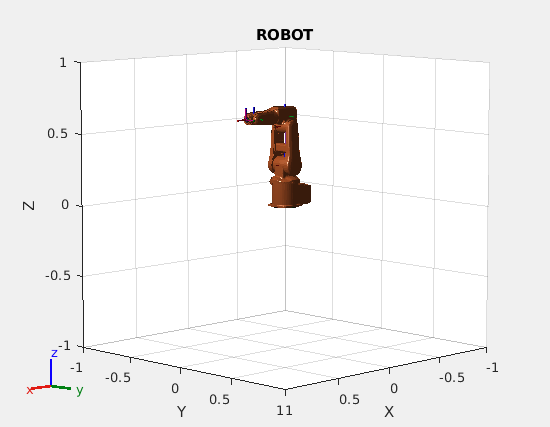

title(ax,'ROBOT');
hold('on');

pts = readtable('DataScience/project/archive/FullWorkspace40K.csv');
pts

pts = 23223×9 table
      Var1        Var2        Var3          Var4         Var5        Var6        Var7         Var8        Var9   
    ________    ________    _________    __________    _________    _______    _________    ________    _________

     -1.3517      1.1116      0.16861    0.00012227      0.13652          0     0.088378    -0.39695     0.069229
       1.379      1.8849     -0.14254      -0.56054      -1.3913          0     0.026135     0.33225     -0.12584
      2.8784      0.6769      0.38934      -0.27564     -0.43413    -3.9412      -0.4207     0.10481      0.22685
    -0.62036     0.35202        0.515    -0.0045852      0.11031          0      0.31093    -0.22219   


x = pts(:,7);
y = pts(:,8);
z = pts(:,9);

x_d = table2array(x);
y_d = table2array(y);
z_d = table2array(z);

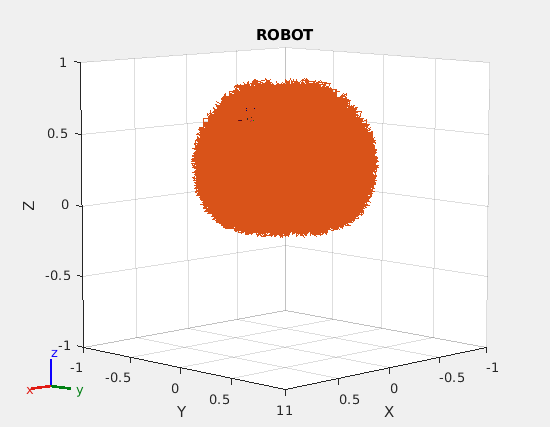

plot3(ax,x_d,y_d,z_d);
hold('off');

robo.BodyNames

ans = 1×8 cell array
    {'base'}    {'link_1'}    {'link_2'}    {'link_3'}    {'link_4'}    {'link_5'}    {'link_6'}    {'tool0'}


i = 1201;
pos = [x_d(i) y_d(i) z_d(i)];
posvec = trvec2tform(pos);
disp(posvec)

    1.0000         0         0    0.0183
         0    1.0000         0   -0.3870
         0         0    1.0000   -0.1347
         0         0         0    1.0000



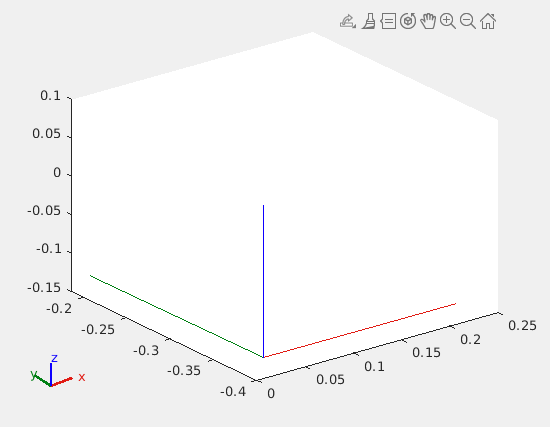

plotTransforms(pos,eul2quat([0 0 0]),FrameSize=0.2);


ik = inverseKinematics("RigidBodyTree",robo);
weights = [0 0 0 1 1 1];
initialguess = homeConfiguration(robo);

[configSoln,solnInfo] = ik("link_6",posvec,weights,initialguess);

disp(configSoln);

  1×6 struct array with fields:

    JointName
    JointPosition



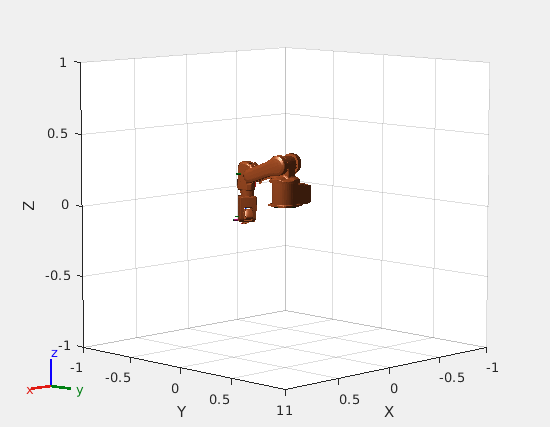

show(robo,configSoln);
hold('off');

pose = getTransform(robo,configSoln,"link_6");
disp(pose);

   -0.4252    0.8723   -0.2414    0.0183
   -0.7798   -0.4885   -0.3916   -0.3870
   -0.4595    0.0218    0.8879   -0.1347
         0         0         0    1.0000



**RANDOM JOINT CONFIGURATION FROM GIVEN DATASET** 

config = pts(i,1:6);
config = table2array(config);
disp('COnfig: ')

COnfig: 


disp(config);

   -1.4241    1.9199   -0.3847    0.6575   -1.0651         0




home_config = homeConfiguration(robo)

home_config = 1×6 struct array with fields:
    JointName
    JointPosition


for i = 1:6
    home_config(i).JointPosition = config(i);
end
newpose = getTransform(robo,home_config,"link_6");
disp(newpose);

   -0.4252    0.8723   -0.2414    0.0183
   -0.7798   -0.4885   -0.3915   -0.3870
   -0.4594    0.0218    0.8879   -0.1347
         0         0         0    1.0000



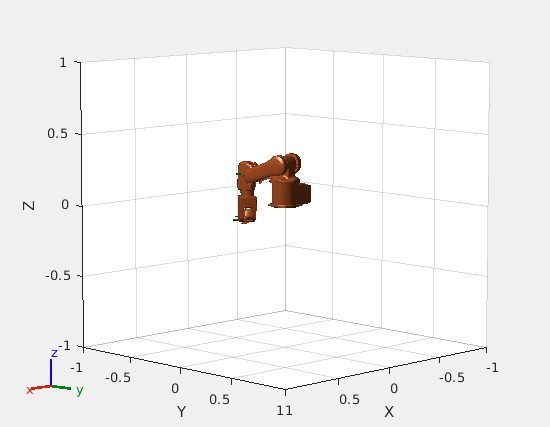

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robo,home_config) 